### **Método da Ponto Fixo (MPF)**


$$x^{k+1} = \Phi(x^{k})$$
 

Vamos resolver utilizando MPF o problema de localizar o zero da função $x^2+x-6=0$, com chute inicial $x_{0}=3$ e $\Phi(x)=\frac{6}{x+1}$.

Graficamente,

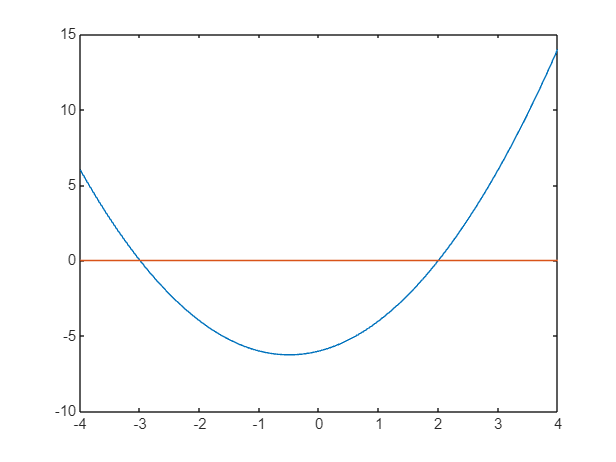

x= -4:0.01:4;
y = x.^2+x-6;
plot(x,y)
hold on
y2 = 0.*x;
plot(x,y2)
hold off

Implementação do MPF:

format long
%Chute inicial
x0 = 3;
fx0 = fun(x0);
k = 0;
tol = 10^-4;
while(abs(fx0) > tol)
    x = fun_it(x0); %atualizando o zero da função usando a função de iteração
    x0 = x;
    fx0 = fun(x0);
    k = k+1;
    xk(k,:) = x0;
    fk(k,:) = fx0;
end
[xk,fk]

ans =   -1.732050807568877  -4.732050807568878
  -2.780656542539707  -1.048605734970830
  -2.963217262122321  -0.182560719582615
  -2.993863267105283  -0.030646004982961
  -2.998977036775254  -0.005113769669971
  -2.999829501284240  -0.000852464508986
  -2.999971583412790  -0.000142082128550
  -2.999995263898393  -0.000023680485604
   1.978416659640840  -0.107450861214742
   2.014493163868995   0.072675871143909


% Melhoria pela função de iteração x = 6/(x+1);

#######################################################

Definindo as funções:

function y = fun(x)
    y = x^2+x-6;
end

function y = fun_it(x)
    y = 6/(x+1);
end